%Mechatronics Homework 1.
%Grounded Joints:ADG



%Joint Coordinates

A = [1.4 0.485 0]

A =     1.4000    0.4850         0


B = [1.67 .99 0]

B =     1.6700    0.9900         0


C = [.255 1.035 0]

C =     0.2550    1.0350         0


D = [.285 .055 0]

D =     0.2850    0.0550         0


E = [.195 2.54 0]

E =     0.1950    2.5400         0


F = [-.98 2.57 0]

F =    -0.9800    2.5700         0


G = [.05 .2 0]

G =     0.0500    0.2000         0




%Point masses
artifactweight = 200

artifactweight = 200

artifactmass = 200/9.81

artifactmass = 20.3874


%Link Lengths

% Define link lengths based on the coordinates
lengthAB = norm(A-B)

lengthAB = 0.5726

lengthBC = norm(B-C)

lengthBC = 1.4157

lengthCD = norm(D-C)

lengthCD = 0.9805

lengthEC = norm(E-C)

lengthEC = 1.5062

lengthDE = norm(E-D)

lengthDE = 2.4866

lengthEF = norm(E-F)

lengthEF = 1.1754

lengthGF = 2.5841

lengthGF = 2.5841

lengthGGripper = lengthGF + 1.843

lengthGGripper = 4.4271

%Calculating gripper joint coordinates:

thetaGF = atan2((F(2)-G(2)),(F(1)-G(1)))

thetaGF = 1.9808

thetaDCE = atan2((E(2)-D(2)),(E(1)-D(1)))

thetaDCE = 1.6070

Grip = [(cos(thetaGF)*lengthGGripper+G(1)) (sin(thetaGF)*lengthGGripper+G(2)) 0]

Grip =    -1.7146    4.2602         0




width = .10;
thickness = .05;
jointdiameter = .06;
density = 7850;

% Define link masses
massAB = 23.34;
massBC = 56.43

massBC = 56.4300

massDE = 97.35

massDE = 97.3500

massEF = 47

massEF = 47

massGF = 190.33

massGF = 190.3300

massGGrip = massGF + artifactmass

massGGrip = 210.7174


%Define link weights
WAB = [0 -massAB*9.81 0]

WAB =          0 -228.9654         0


WBC = [0 -massBC*9.81 0]

WBC =          0 -553.5783         0


WDE = [0 -massDE*9.81 0]

WDE =          0 -955.0035         0


WEF = [0 -massEF*9.81 0]

WEF =          0 -461.0700         0


WGF = [0 -massGF*9.81 0]

WGF = 1.0e+03 *

         0   -1.8671         0


WGGrip = [0 -massGGrip*9.81 0]

WGGrip = 1.0e+03 *

         0   -2.0671         0




%Center of mass of each link
S1 = (A+B)/2

S1 =     1.5350    0.7375         0


S2 = (B+C)/2

S2 =     0.9625    1.0125         0


S3 = [(cos(thetaDCE)*1.2463+D(1)) (sin(thetaDCE)*1.2463+D(2)) 0]

S3 =     0.2399    1.3005         0


lengthFGripper = norm(Grip-F)

lengthFGripper = 1.8430

S4 = (F+E)/2

S4 =    -0.3925    2.5550         0


S5minusartifact = [(cos(thetaGF)*2.4263+G(1)) (sin(thetaGF)*2.4263+G(2)) 0]

S5minusartifact =    -0.9171    2.4252         0


S5= (S5minusartifact*massGF + artifactmass*Grip)/(massGF+artifactmass)

S5 =    -0.9942    2.6028         0



lengthS5minusF = norm(S5minusartifact-F)

lengthS5minusF = 0.1578

lengthS5G = norm(S5-G)

lengthS5G = 2.6199

lengthS5F = lengthS5G - lengthGF

lengthS5F = 0.0358

lengthS5minusG=norm(S5minusartifact-G)

lengthS5minusG = 2.4263

lengthS5minusS5with=norm(S5minusartifact-S5)

lengthS5minusS5with = 0.1936

lengthS3D = norm(S3-D)

lengthS3D = 1.2463

lengthS3E = norm(S3-E)

lengthS3E = 1.2403

lengthS5Gripper = norm(S5-Grip);







%Newton's II law
%Angular velocity and angular acceleration?
%Calculating instantaneous angular velocity under assumptions.
omegaAB_RPM = 23.148

omegaAB_RPM = 23.1480

omegaAB = omegaAB_RPM*(2*pi/60)

omegaAB = 2.4241


%Angular Acceleration
%Calculating instantaneous angular acceleration under assumptions.
%alphaGF = d_omega/d_t = (d_theta/d_t) * (d_omega/d_theta)
alphaAB = 0

alphaAB = 0


vector_alphaAB = [0 0 alphaAB];




%Newton's Second Law
%complex mass moment of inertia
J_AB = .74;
J_ED = 51.79;
J_GripperG = 379.79 + artifactmass*(lengthS5Gripper)^2;
J_CB = 9.85;
J_FE = 5.73;



%Positional Analysis

%Circle Intersection Technique

%Joint coordinates have been defined
%length of links also defined.

%Compute initial angle of input link AB.

initial_theta = atan2(B(2)-A(2),B(1)-A(1));

if (initial_theta<0)
   inputAngle = 2*pi + initial_theta;
else
    inputAngle = initial_theta;
end

for theta=0:1:360
% new position of joint A
theta;

B_new = [A(1)+lengthAB*cos(inputAngle+deg2rad(theta)), A(2)+lengthAB*sin(inputAngle+deg2rad(theta)), 0];

[Cx,Cy]= circcirc(B_new(1),B_new(2),lengthBC,D(1),D(2),lengthCD);

%Check if NaN

circIntersect_x = any(isnan(vpa(Cx)));
circIntersect_y = any(isnan(vpa(Cy)));

if circIntersect_x == 0 && circIntersect_y == 0
C_1 = [Cx(1) Cy(1) 0];
C_2 = [Cx(2) Cy(2) 0];

%distance to determine whether C_1 or C_2 is correct

dist1 = norm(C_1-C);
dist2 = norm(C_2-C);

if(dist1<dist2)
    C_new = vpa(C_1);

else

    C_new = vpa(C_2);
end

%New Position of Joint E using C_new

[Ex,Ey]= circcirc(C_new(1),C_new(2),lengthEC,D(1),D(2),lengthDE);

%Check if there is NaN
circIntersect_x = any(isnan(vpa(Ex)));
circIntersect_y = any(isnan(vpa(Ey)));

if circIntersect_x == 0 && circIntersect_y == 0
    E_1 = [Ex(1) Ey(1) 0];
    E_2 = [Ex(2) Ey(2) 0];


    dist1 = norm(E_1-E);
    dist2 = norm(E_2-E);


if(dist1<dist2)
    E_new = vpa(E_1);

else

    E_new = vpa(E_2);
end

%New Position of Joint F using E_new and G
[Fx,Fy]= circcirc(E_new(1),E_new(2),lengthEF,G(1),G(2),lengthGF);

%Check if there is NaN
circIntersect_x = any(isnan(vpa(Fx)));
circIntersect_y = any(isnan(vpa(Fy)));

if circIntersect_x == 0 && circIntersect_y == 0
    F_1 = [Fx(1) Fy(1) 0];
    F_2 = [Fx(2) Fy(2) 0];


    dist1 = norm(F_1-F);
    dist2 = norm(F_2-F);

if(dist1<dist2)
    F_new = vpa(F_1);

else

    F_new = vpa(F_2);
end

%New Position of S3 using E_new and D
[S3x,S3y]= circcirc(E_new(1),E_new(2),lengthS3E,D(1),D(2),lengthS3D);

%Check if there is NaN
circIntersect_x = any(isnan(vpa(S3x)));
circIntersect_y = any(isnan(vpa(S3y)));

if circIntersect_x == 0 && circIntersect_y == 0
    S3_1 = [S3x(1) S3y(1) 0];
    S3_2 = [S3x(2) S3y(2) 0];


    dist1 = norm(S3_1-S3);
    dist2 = norm(S3_2-S3);

if(dist1<dist2)
    S3_new = vpa(S3_1);

else

    S3_new = vpa(S3_2);
end


%Taking Artifact Into Account
if theta<301.13 && theta>121.13
    [S5x,S5y]= circcirc(F_new(1),F_new(2),lengthS5F,G(1),G(2),lengthS5G);
    J_GripperG = 379.79 + artifactmass*(lengthS5Gripper)^2 + massGF*(lengthS5minusS5with)^2;
    massGGrip=massGF+artifactmass;
    WGGrip = [0 -massGGrip*9.81 0];
else
    [S5x,S5y]= circcirc(F_new(1),F_new(2),lengthS5minusF,G(1),G(2),lengthS5minusG);
    J_GripperG = 379.79;
    WGGrip=WGF;
    massGGrip=massGF;
end



%Check if there is NaN
circIntersect_x = any(isnan(vpa(S5x)));
circIntersect_y = any(isnan(vpa(S5y)));

if circIntersect_x == 0 && circIntersect_y == 0
    S5_1 = [S5x(1) S5y(1) 0];
    S5_2 = [S5x(2) S5y(2) 0];


    dist1 = norm(S5_1-S5);
    dist2 = norm(S5_2-S5);

if(dist1<dist2)
    S5_new = vpa(S5_1);

else

    S5_new = vpa(S5_2);
end




%Store values for plotting
new_B_x((theta+1),:) = B_new(1);
new_B_y((theta+1),:) = B_new(2);
new_C_x((theta+1),:) = C_new(1);
new_C_y((theta+1),:) = C_new(2);
new_E_x((theta+1),:) = E_new(1);
new_E_y((theta+1),:) = E_new(2);
new_F_x((theta+1),:) = F_new(1);
new_F_y((theta+1),:) = F_new(2);

B = B_new;
C = C_new;
E = E_new;
F = F_new;
S3=S3_new;
S5=S5_new;

else
    fprintf('New position of S5 cannot be determined at angle: %d degree', theta)
break
end

else
    fprintf('New position of S3 cannot be determined at angle: %d degree', theta)
break
end

else
    fprintf('New position of F cannot be determined at angle: %d degree', theta)
break
end

else
    fprintf('New position of E cannot be determined at angle: %d degree', theta)
break
end

else
    fprintf('New position of C cannot be determined at angle: %d degree', theta)
break
end



%Implicit Center of mass of links
S1 = (A+B)/2;
S2 = (B+C)/2;
S4 = (F+E)/2;
S3_PAtest((theta+1),:)=S3_new;
S5_PAtest((theta+1),:)=S5_new;

%Calculate forces and torque based on static equilibrium conditions
syms FAx FAy FBx FBy FCx FCy FDx FDy FEx FEy FFx FFy FGx FGy Tin

ForceA = [FAx FAy 0];
ForceB = [FBx FBy 0];
ForceC = [FCx FCy 0];
ForceD = [FDx FDy 0];
ForceE = [FEx FEy 0];
ForceF = [FFx FFy 0];
ForceG = [FGx FGy 0];
InputTorque = [0 0 Tin];


%Forces
%ForceAB
eqn1 = ForceA + ForceB + WAB == 0;
%ForceBC
eqn2 = -ForceB + ForceC + WBC == 0;
%ForceCDE
eqn3 = -ForceC + ForceD + ForceE + WDE == 0;
%ForceEF
eqn4 = -ForceE + ForceF + WEF == 0;
%ForceGGrip
eqn5 = WGGrip + ForceG -ForceF == 0;

%Moments
%MomentAB
eqn6 = InputTorque + cross(A-S1,ForceA) + cross(B-S1,ForceB) == 0;
%MomentBC
eqn7 = cross(C-S2, ForceC) + cross(B-S2,-ForceB) == 0;
%MomentCDE
eqn8 = cross(C-S3, -ForceC) + cross(D-S3, ForceD) + cross(E-S3, ForceE) == 0;
%MomentEF
eqn9 = cross(E-S4, -ForceE) + cross(F-S4, ForceF) == 0;
%MomentGGrip
eqn10 = cross(G-S5, ForceG) + cross(F-S5, -ForceF) == 0;

eqnmatrix = [eqn1, eqn2, eqn3, eqn4, eqn5, eqn6, eqn7, eqn8, eqn9, eqn10,];
% Solve the system of equations for the unknown forces and torque
staticsolution = solve(eqnmatrix, [FAx, FAy, FBx, FBy, FCx, FCy, FDx, FDy, FEx, FEy, FFx, FFy, FGx, FGy, Tin]);

x_theta((theta+1),1)=theta;
ForceA_PA((theta+1),:) = sqrt((double(staticsolution.FAx))^2 + (double(staticsolution.FAy))^2);
ForceB_PA((theta+1),:) = sqrt((double(staticsolution.FBx))^2 + (double(staticsolution.FBy))^2);
ForceC_PA((theta+1),:) = sqrt((double(staticsolution.FCx))^2 + (double(staticsolution.FCy))^2);
ForceD_PA((theta+1),:) = sqrt((double(staticsolution.FDx))^2 + (double(staticsolution.FDy))^2);
ForceE_PA((theta+1),:) = sqrt((double(staticsolution.FEx))^2 + (double(staticsolution.FEy))^2);
ForceF_PA((theta+1),:) = sqrt((double(staticsolution.FFx))^2 + (double(staticsolution.FFy))^2);
ForceG_PA((theta+1),:) = sqrt((double(staticsolution.FGx))^2 + (double(staticsolution.FGy))^2);


vectorForceA_PA((theta+1),:) = [double(staticsolution.FAx) double(staticsolution.FAy), 0];
vectorForceB_PA((theta+1),:) = [double(staticsolution.FBx) double(staticsolution.FBy), 0];
vectorForceC_PA((theta+1),:) = [double(staticsolution.FCx) double(staticsolution.FCy), 0];
vectorForceD_PA((theta+1),:) = [double(staticsolution.FDx) double(staticsolution.FDy) 0];
vectorForceE_PA((theta+1),:) = [double(staticsolution.FEx) double(staticsolution.FEy) 0];
vectorForceF_PA((theta+1),:) = [double(staticsolution.FFx) double(staticsolution.FFy) 0];
vectorForceG_PA((theta+1),:) = [double(staticsolution.FGx) double(staticsolution.FGy) 0];
vectorTorquein_PA((theta+1),:) = [0 0 double(staticsolution.Tin)];



%Newton's II law
%Angular velocity and angular acceleration?


%loop ADCBA
syms wCB wED

vector_omegaAB = [0 0 omegaAB];
omegaCB = [0 0 wCB];
omegaED = [0 0 wED];

eqn12 = cross(omegaED, D-C) + cross(omegaCB, C-B) + cross(vector_omegaAB, B-A) == 0;
loop2Solution = solve(eqn12,[wCB,wED]);

angularVelocity_CB = double(loop2Solution.wCB);
angularVelocity_ED = double(loop2Solution.wED);

vector_omegaCB = [0 0 angularVelocity_CB];
vector_omegaED = [0 0 angularVelocity_ED];

vector_omegaCB_PA((theta+1),:) = [0 0 angularVelocity_CB];
vector_omegaAB_PA((theta+1),:) = vector_omegaAB;
vector_omegaED_PA((theta+1),:) = [0 0 angularVelocity_ED];

%Loop DEFGD
syms wFE wFG

omegaFE = [0 0 wFE];
omegaFG = [0 0 wFG];

eqn11 = cross(omegaFG,G-F) + cross(omegaFE,F-E) + cross(vector_omegaED,E-D) == 0;

loop1Solution = solve(eqn11,[wFE wFG]);
angularVelocity_FE = double(loop1Solution.wFE);
angularVelocity_FG = double(loop1Solution.wFG);

vector_omegaFE = [0 0 angularVelocity_FE];
vector_omegaFG = [0 0 angularVelocity_FG];
vector_omegaFG_PA((theta+1),:)=[0 0 angularVelocity_FG];
vector_omegaFE_PA((theta+1),:) = [0 0 angularVelocity_FE];


%Angular Acceleration
%Calculating instantaneous angular acceleration under assumptions.
%alphaGF = d_omega/d_t = (d_theta/d_t) * (d_omega/d_theta)
alphaAB = 0;

vector_alphaAB = [0 0 alphaAB];
vector_alphaAB_PA((theta+1),:) = [0 0 alphaAB];


%loop ADCBA

syms aCB aED

alphaCB = [0 0 aCB];
alphaED = [0 0 aED];

a_ED = cross(alphaED,D-C) + cross(vector_omegaED,cross(vector_omegaED,D-C));
a_CB = cross(alphaCB,C-B) + cross(vector_omegaCB,cross(vector_omegaCB,C-B));
a_BA = cross(vector_alphaAB,B-A) + cross(vector_omegaAB,cross(vector_omegaAB,B-A));
eqn14 = a_ED + a_CB + a_BA == 0;

loop2angularaccels = solve(eqn14,[aCB,aED]);

vector_alphaCB = [0 0 double(loop2angularaccels.aCB)];
vector_alphaED = [0 0 double(loop2angularaccels.aED)];
vector_alphaCB_PA((theta+1),:) = [0 0 double(loop2angularaccels.aCB)];
vector_alphaED_PA((theta+1),:) = [0 0 double(loop2angularaccels.aED)];

%loop GFEDG

syms aFE aGF

alphaFE = [0 0 aFE];
alphaGF = [0 0 aGF];

a_FG = cross(alphaGF,G-F)+cross(vector_omegaFG,cross(vector_omegaFG,G-F));
a_EF = cross(alphaFE,F-E) + cross(vector_omegaFE,cross(vector_omegaFE,F-E));
a_DE = cross(vector_alphaED,E-D) + cross(vector_omegaED,cross(vector_omegaED,E-D));
eqn13 = a_FG + a_EF + a_DE == 0;

loop1angularaccels = solve(eqn13,[aFE,aGF]);

vector_alphaFE = [0 0 double(loop1angularaccels.aFE)];
vector_alphaGF = [0 0 double(loop1angularaccels.aGF)];
vector_alphaFE_PA((theta+1),:) = [0 0 double(loop1angularaccels.aFE)];
vector_alphaGF_PA((theta+1),:) = [0 0 double(loop1angularaccels.aGF)];



%Velocity at Joints with respect to ground

%Velocity at B
vectorvB_A = cross(vector_omegaAB,B-A);

vectorvB_A_PA((theta+1),:) = cross(vector_omegaAB,B-A);

%Velocity at C
vectorvC_D = cross(vector_omegaED,C-D);
vectorvC_D_PA((theta+1),:) = cross(vector_omegaED,C-D);

%Velocity at E
vectorvE_D = cross(vector_omegaED, E-D);
vectorvE_D_PA((theta+1),:) = cross(vector_omegaED, E-D);

%Velocity at F
vectorvF_G = cross(vector_omegaFG, F-G);
vectorvF_G_PA((theta+1),:) = cross(vector_omegaFG, F-G);


%Accelerations at Joints with respect to ground

%Accel B
vectoraB_A = cross(vector_alphaAB,B-A) + cross(vector_omegaAB,cross(vector_omegaAB,B-A));
vectoraB_A_PA((theta+1),:) = cross(vector_alphaAB,B-A) + cross(vector_omegaAB,cross(vector_omegaAB,B-A));

%AccelC
vectoraC_D = cross(vector_alphaED,C-D) + cross(vector_omegaED,cross(vector_omegaED,C-D));
vectoraC_D_PA((theta+1),:) = cross(vector_alphaED,C-D) + cross(vector_omegaED,cross(vector_omegaED,C-D));

%AccelE
vectoraE_D = cross(vector_alphaED,E-D) + cross(vector_omegaED,cross(vector_omegaED,E-D));
vectoraE_D_PA((theta+1),:) = cross(vector_alphaED,E-D) + cross(vector_omegaED,cross(vector_omegaED,E-D));

%AccelF
vectoraF_G = cross(vector_alphaGF,F-G) + cross(vector_omegaFG,cross(vector_omegaFG,F-G));
vectoraF_G_PA((theta+1),:) = cross(vector_alphaGF,F-G) + cross(vector_omegaFG,cross(vector_omegaFG,F-G));



%Velocities and accelerations for each cm


%V_S1/A = cross(omega_AB,S1-A)

v_S1_A = cross(vector_omegaAB, S1-A);
v_S1_A_PA((theta+1),:) = cross(vector_omegaAB, S1-A);

%v_S2_A = V_S2_B + V B_A

v_S2_B = cross(vector_omegaCB,S2-B);
v_S2_A = v_S2_B + vectorvB_A;
v_S2_A_PA((theta+1),:) = v_S2_B + vectorvB_A;

%v_S3_D
v_S3_D = cross(vector_omegaED,S3-D);
v_S3_D_PA((theta+1),:) = cross(vector_omegaED,S3-D);

%v_S5_G= cross(vectoromegaGF,S5-G)
v_S5_G = cross(vector_omegaFG,S5-G);
v_S5_G_PA((theta+1),:) = cross(vector_omegaFG,S5-G);

%v_S4_G = v_S4_F+v_FG
v_S4_G = cross(vector_omegaFE,S4-F) + vectorvF_G;
v_S4_G_PA((theta+1),:) = cross(vector_omegaFE,S4-F) + vectorvF_G;

%a_S1_A
a_S1_A = cross(vector_alphaAB,S1-A) + cross(vector_omegaAB,cross(vector_omegaAB,S1-A));
a_S1_A_PA((theta+1),:) = cross(vector_alphaAB,S1-A) + cross(vector_omegaAB,cross(vector_omegaAB,S1-A));

%a_S2_A= vectoraS2_B+vectoraBA
a_S2_A = vectoraB_A + cross(vector_alphaCB,S2-B) + cross(vector_omegaCB,cross(vector_omegaCB,S2-B));
a_S2_A_PA((theta+1),:) = vectoraB_A + cross(vector_alphaCB,S2-B) + cross(vector_omegaCB,cross(vector_omegaCB,S2-B));

%a_S3_D
a_S3_D = cross(vector_alphaED,S3-D) + cross(vector_omegaED,cross(vector_omegaED,S3-D));
a_S3_D_PA((theta+1),:) = cross(vector_alphaED,S3-D) + cross(vector_omegaED,cross(vector_omegaED,S3-D));

%a_S4_G= vectoraS4_F+ vectoraF_G
a_S4_G = vectoraF_G + cross(vector_alphaFE,S4-F) + cross(vector_omegaFE,cross(vector_omegaFE,S4-F));
a_S4_G_PA((theta+1),:) = vectoraF_G + cross(vector_alphaFE,S4-F) + cross(vector_omegaFE,cross(vector_omegaFE,S4-F));

%a_S5_G
a_S5_G = cross(vector_alphaGF,S5-G)+ cross(vector_omegaFG,cross(vector_omegaFG,S5-G));
a_S5_G_PA((theta+1),:) = cross(vector_alphaGF,S5-G)+ cross(vector_omegaFG,cross(vector_omegaFG,S5-G));

%Newton's Second Law

syms NFAx NFAy NFBx NFBy NFCx NFCy NFDx NFDy NFEx NFEy NFFx NFFy NFGx NFGy NTin
%Define forces

NForceA = [NFAx NFAy 0];
NForceB = [NFBx NFBy 0];
NForceC = [NFCx NFCy 0];
NForceD= [NFDx NFDy 0];
NForceE= [NFEx NFEy 0];
NForceF = [NFFx NFFy 0];
NForceG = [NFGx NFGy 0];
Torqueinput = [0 0 NTin];

%Equations for link AB
%Sum of forces
eqn15 = NForceA + NForceB + WAB == massAB*a_S1_A;
%Sum of moments
eqn16 = cross(A-S1,NForceA) + cross(B-S1,NForceB) + Torqueinput == J_AB*vector_alphaAB;

%Equations for link BC
%Sum of forces
eqn17 = -NForceB + NForceC + WBC == massBC*a_S2_A;
%Sum of moments
eqn18 = cross(B-S2,-NForceB) + cross(C-S2,NForceC) == J_CB*vector_alphaCB;

%Equations for link CDE
%Sum of forces
eqn19 = -NForceC + NForceD + NForceE + WDE == massDE*a_S3_D;
%Sum of moments
eqn20 = cross(C-S3,-NForceC) + cross(D-S3,NForceD) == J_ED*vector_alphaED;

%Equations for link EF
%Sum of forces
eqn21 = -NForceE + NForceF + WEF == massEF*a_S4_G;
%Sum of moments
eqn22 = cross(F-S4,NForceF) + cross(E-S4,-NForceE) == J_FE*vector_alphaFE;

%Equations for link FG
%Sum of forces
eqn23 = -NForceF + NForceG + WGGrip == massGGrip*a_S5_G;

%Sum of moments
eqn24 = cross(F-S5,-NForceF) + cross(G-S5,NForceG) == J_GripperG*vector_alphaGF;

%Solving equations
NeqnMatrix = [eqn15, eqn16, eqn17, eqn18, eqn19, eqn20, eqn21, eqn22, eqn23, eqn24];
DynamicSolution = solve(NeqnMatrix, [NFAx, NFAy, NFBx, NFBy, NFCx, NFCy, NFDx, NFDy, NFEx, NFEy, NFFx, NFFy, NFGx, NFGy, NTin]);

%Extract forces from the dynamic solution
NForce_Ax = double(DynamicSolution.NFAx);
NForce_Ay = double(DynamicSolution.NFAy);
NForce_A = sqrt((NForce_Ay)^2+(NForce_Ax)^2);
NForce_Bx = double(DynamicSolution.NFBx);
NForce_By = double(DynamicSolution.NFBy);
NForce_B = sqrt((NForce_By)^2+(NForce_Bx)^2);
NForce_Cx = double(DynamicSolution.NFCx);
NForce_Cy = double(DynamicSolution.NFCy);
NForce_C = sqrt((NForce_Cy)^2+(NForce_Cx)^2);
NForce_Dx = double(DynamicSolution.NFDx);
NForce_Dy = double(DynamicSolution.NFDy);
NForce_D = sqrt((NForce_Dy)^2+(NForce_Dx)^2);
NForce_Ex = double(DynamicSolution.NFEx);
NForce_Ey = double(DynamicSolution.NFEy);
NForce_E = sqrt((NForce_Ey)^2+(NForce_Ex)^2);
NForce_Fx = double(DynamicSolution.NFFx);
NForce_Fy = double(DynamicSolution.NFFy);
NForce_F = sqrt((NForce_Fy)^2+(NForce_Fx)^2);
NForce_Gx = double(DynamicSolution.NFGx);
NForce_Gy = double(DynamicSolution.NFGy);
NForce_G = sqrt((NForce_Gy)^2+(NForce_Gx)^2);
NTorque = double(DynamicSolution.NTin);

VectorNTorque = [0, 0, NTorque];

VectorNForceA_PA((theta+1),:) = NForce_A;

VectorNForceB_PA((theta+1),:) = NForce_B;

VectorNForceC_PA((theta+1),:) = NForce_C;

VectorNForceD_PA((theta+1),:) = NForce_D;

VectorNForceE_PA((theta+1),:) = NForce_E;

VectorNForceF_PA((theta+1),:) = NForce_F;

VectorNForceG_PA((theta+1),:) = NForce_G;
VectorNTorque_PA((theta+1),:) = [0, 0, NTorque];

NForceA_PA((theta+1),:) = [NForce_Ax NForce_Ay 0];
NForceB_PA((theta+1),:) = [NForce_Bx NForce_By 0];
NForceC_PA((theta+1),:) = [NForce_Cx NForce_Cy 0];
NForceD_PA((theta+1),:) = [NForce_Dx NForce_Dy 0];
NForceE_PA((theta+1),:) = [NForce_Ex NForce_Ey 0];
NForceF_PA((theta+1),:) = [NForce_Fx NForce_Fy 0];
NForceG_PA((theta+1),:) = [NForce_Gx NForce_Gy 0];
end



%Plots
plot(x_theta,ForceA_PA(:,1),"r-"); hold on


plot(x_theta,ForceB_PA(:,1),"y-")


plot(x_theta,ForceC_PA(:,1),"g-")


plot(x_theta,ForceD_PA(:,1),"c-")


plot(x_theta,ForceE_PA(:,1),"m-")

plot(x_theta,ForceF_PA(:,1),"k-")

plot(x_theta,ForceG_PA(:,1),"b-")

plot(x_theta,vectorTorquein_PA(:,3),"r-.")

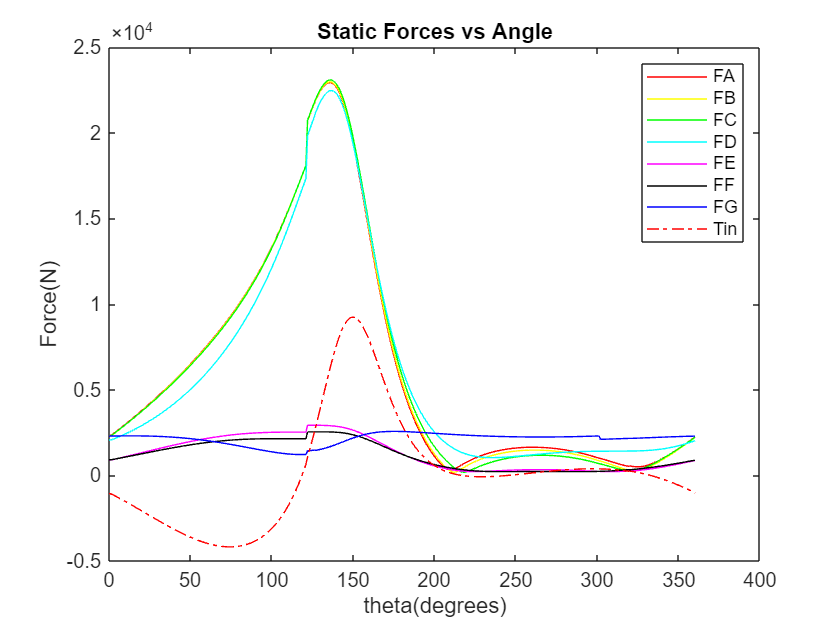

legend("FA","FB", "FC","FD","FE","FF","FG","Tin")
title("Static Forces vs Angle")
xlabel('theta(degrees)')
ylabel('Force(N)')
hold off

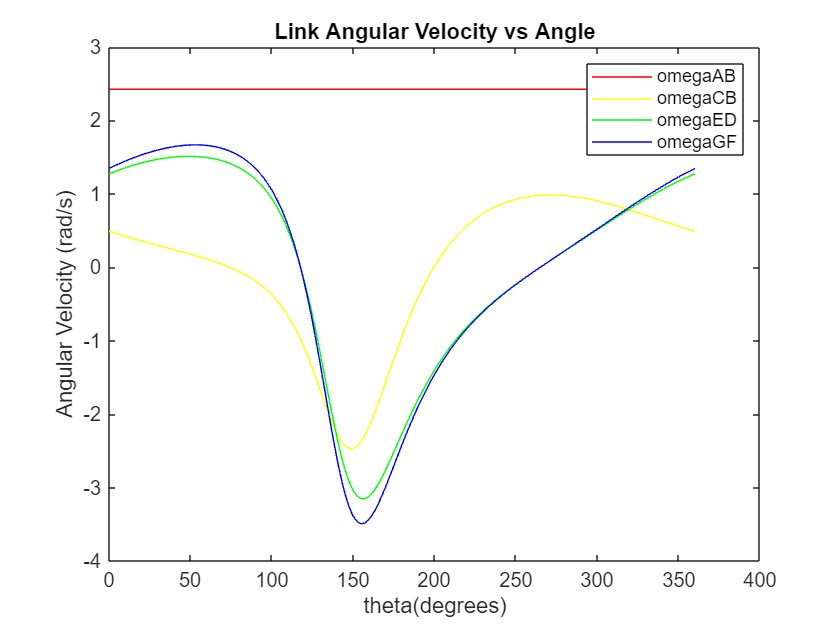




plot(x_theta,vector_omegaAB_PA(:,3),"r-"); hold on
plot(x_theta,vector_omegaCB_PA(:,3),"y-")
plot(x_theta,vector_omegaED_PA(:,3),"g-")
plot(x_theta,vector_omegaFG_PA(:,3),"b-")
legend("omegaAB","omegaCB","omegaED","omegaGF")
title("Link Angular Velocity vs Angle")
xlabel('theta(degrees)')
ylabel('Angular Velocity (rad/s)')
hold off

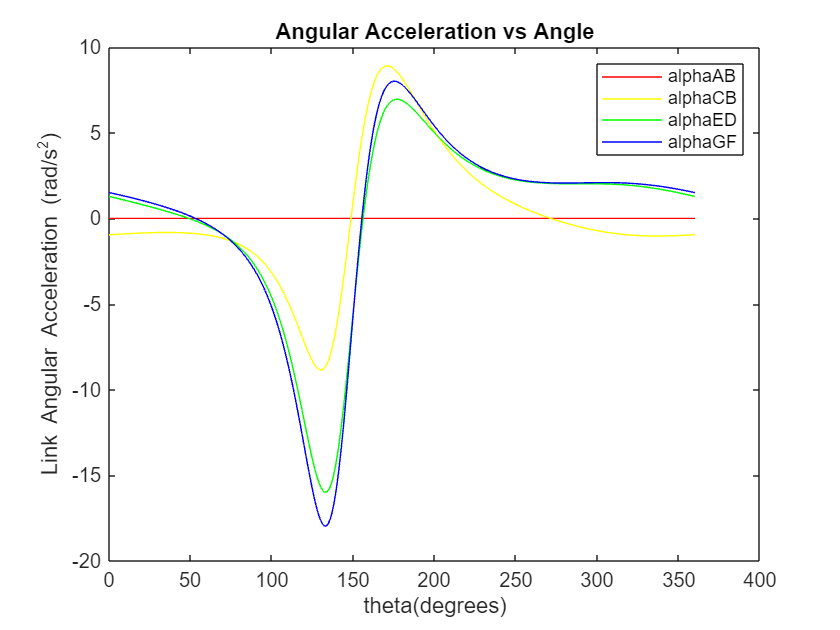


figure(3);
plot(x_theta,vector_alphaAB_PA(:,3),"r-"); hold on
plot(x_theta,vector_alphaCB_PA(:,3),"y-")
plot(x_theta,vector_alphaED_PA(:,3),"g-")
plot(x_theta,vector_alphaGF_PA(:,3),"b-")
legend("alphaAB","alphaCB","alphaED","alphaGF")
xlabel('theta(degrees)')
ylabel('Link Angular Acceleration (rad/s^2)')
title('Angular Acceleration vs Angle')

hold off

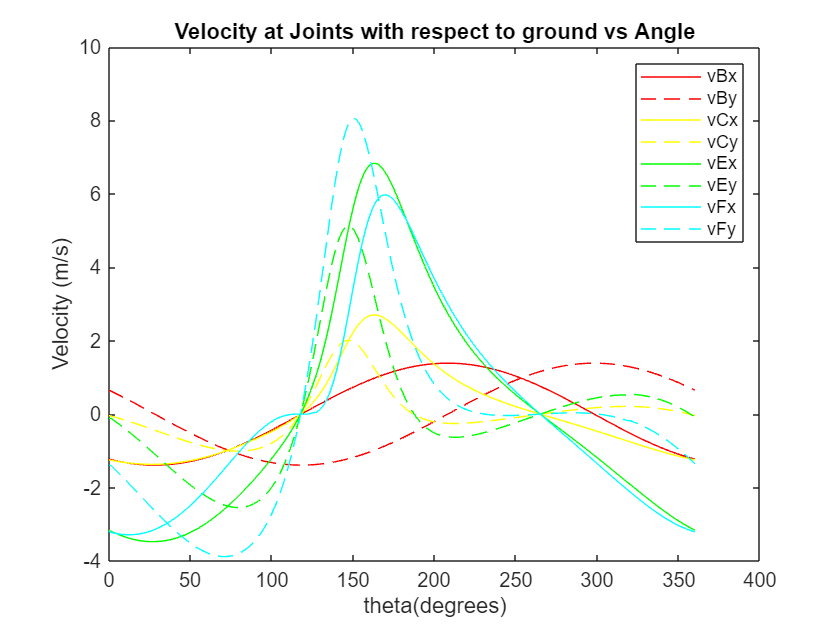



plot(x_theta,vectorvB_A_PA(:,1),"r-"); hold on

plot(x_theta,vectorvB_A_PA(:,2),"r--")

plot(x_theta,vectorvC_D_PA(:,1),"y-")

plot(x_theta,vectorvC_D_PA(:,2),"y--")

plot(x_theta,vectorvE_D_PA(:,1),"g-")

plot(x_theta,vectorvE_D_PA(:,2),"g--")

plot(x_theta,vectorvF_G_PA(:,1),"c-")

plot(x_theta,vectorvF_G_PA(:,2),"c--")
legend("vBx", "vBy","vCx", "vCy","vEx", "vEy","vFx", "vFy")
title("Velocity at Joints with respect to ground vs Angle")
xlabel('theta(degrees)')
ylabel('Velocity (m/s)')
hold off

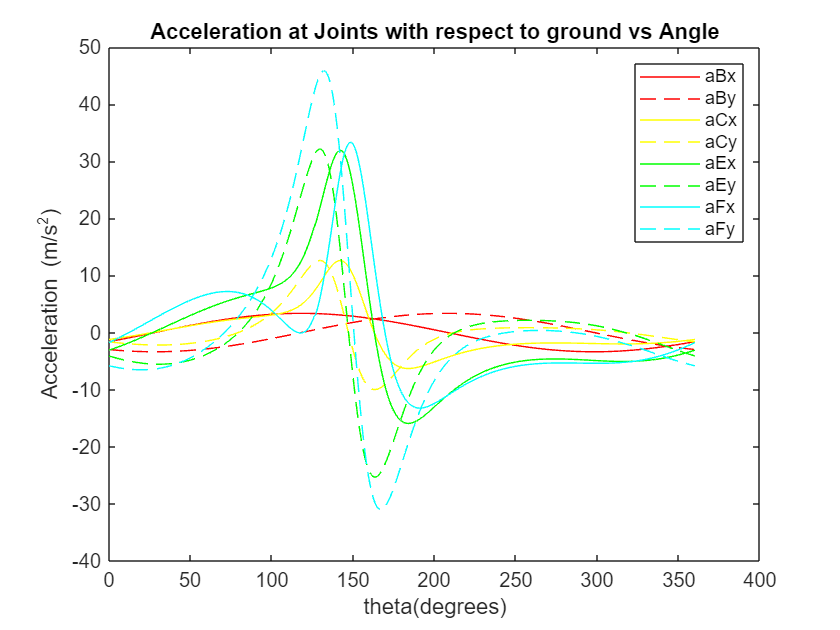


figure(5);
plot(x_theta,vectoraB_A_PA(:,1),"r-"); hold on

plot(x_theta,vectoraB_A_PA(:,2),"r--")

plot(x_theta,vectoraC_D_PA(:,1),"y-")

plot(x_theta,vectoraC_D_PA(:,2),"y--")

plot(x_theta,vectoraE_D_PA(:,1),"g-")

plot(x_theta,vectoraE_D_PA(:,2),"g--")

plot(x_theta,vectoraF_G_PA(:,1),"c-")

plot(x_theta,vectoraF_G_PA(:,2),"c--")
legend("aBx", "aBy","aCx", "aCy","aEx", "aEy","aFx", "aFy")
title("Acceleration at Joints with respect to ground vs Angle")
xlabel('theta(degrees)')
ylabel('Acceleration (m/s^2)')
hold off



plot(x_theta,v_S1_A_PA(:,1),"r-"); hold on

plot(x_theta,v_S1_A_PA(:,2),"r--")

plot(x_theta,v_S2_A_PA(:,1),"y-")

plot(x_theta,v_S2_A_PA(:,2),"y--")

plot(x_theta,v_S3_D_PA(:,1),"g-")


plot(x_theta,v_S3_D_PA(:,2),"g--")

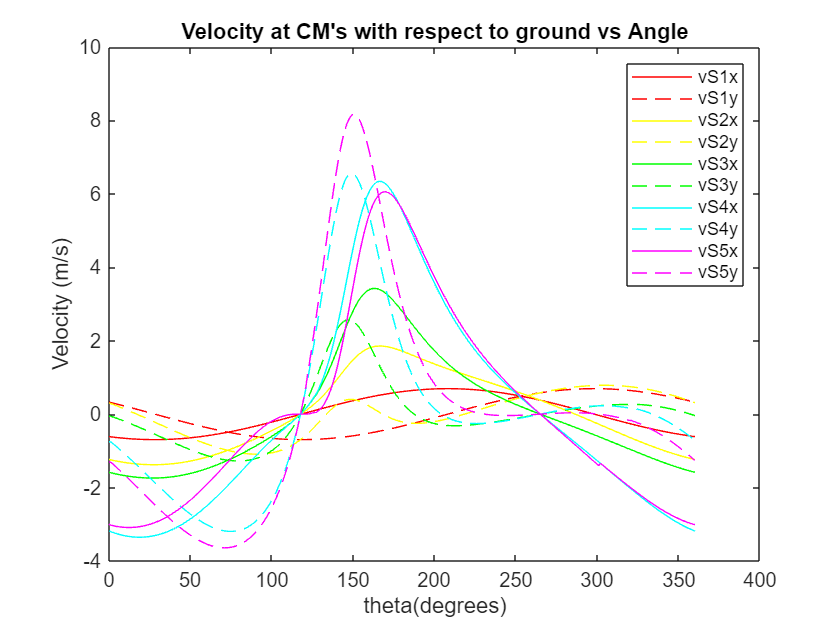


plot(x_theta,v_S4_G_PA(:,1),"c-")

plot(x_theta,v_S4_G_PA(:,2),"c--")

plot(x_theta,v_S5_G_PA(:,1),"m-")

plot(x_theta,v_S5_G_PA(:,2),"m--")
legend("vS1x", "vS1y","vS2x", "vS2y","vS3x", "vS3y","vS4x", "vS4y","vS5x", "vS5y")
title("Velocity at CM's with respect to ground vs Angle")
xlabel('theta(degrees)')
ylabel('Velocity (m/s)')
hold off


plot(x_theta,a_S1_A_PA(:,1),"r-"); hold on

plot(x_theta,a_S1_A_PA(:,2),"r--")

plot(x_theta,a_S2_A_PA(:,1),"y-")

plot(x_theta,a_S2_A_PA(:,2),"y--")

plot(x_theta,a_S3_D_PA(:,1),"g-")


plot(x_theta,a_S3_D_PA(:,2),"g--")

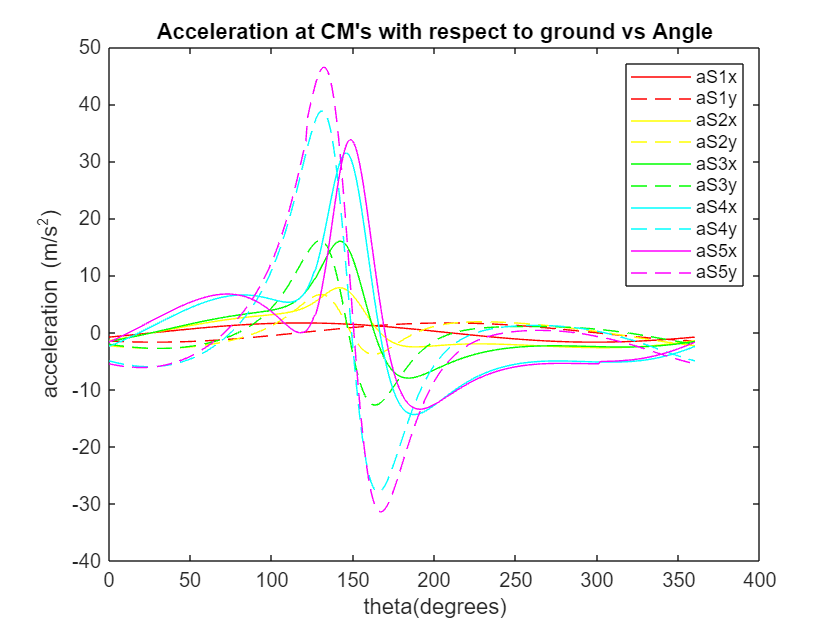


plot(x_theta,a_S4_G_PA(:,1),"c-")

plot(x_theta,a_S4_G_PA(:,2),"c--")

plot(x_theta,a_S5_G_PA(:,1),"m-")

plot(x_theta,a_S5_G_PA(:,2),"m--")
legend("aS1x", "aS1y","aS2x", "aS2y","aS3x", "aS3y","aS4x", "aS4y","aS5x", "aS5y")
title("Acceleration at CM's with respect to ground vs Angle")
xlabel('theta(degrees)')
ylabel('acceleration (m/s^2)')
hold off


plot(x_theta,VectorNForceA_PA(:,1),"r-"); hold on


plot(x_theta,VectorNForceB_PA(:,1),"y-")


plot(x_theta,VectorNForceC_PA(:,1),"g-")


plot(x_theta,VectorNForceD_PA(:,1),"c-")


plot(x_theta,VectorNForceE_PA(:,1),"m-")

plot(x_theta,VectorNForceF_PA(:,1),"k-")

plot(x_theta,VectorNForceG_PA(:,1),"b-")

plot(x_theta,VectorNTorque_PA(:,3),"r:")

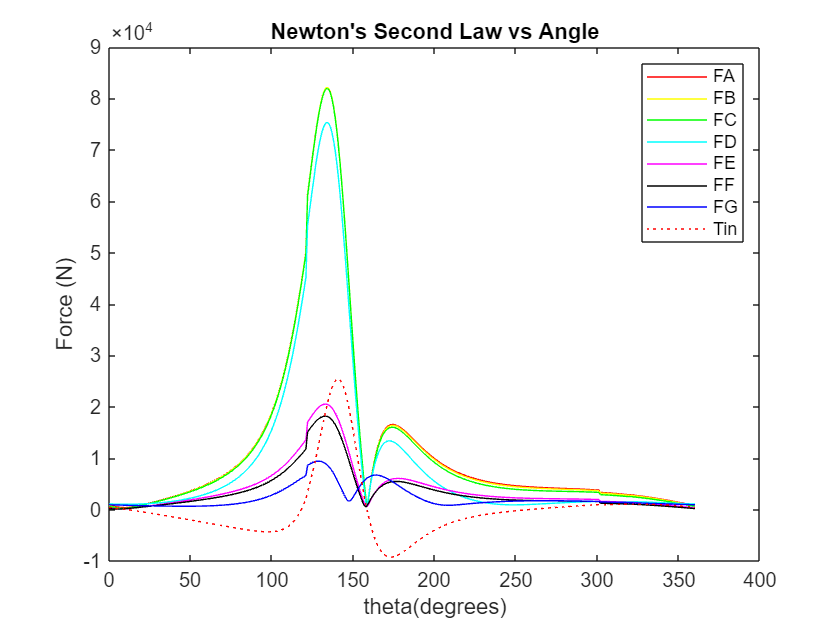

legend("FA","FB","FC","FD","FE","FF","FG","Tin")
title("Newton's Second Law vs Angle")
xlabel('theta(degrees)')
ylabel('Force (N)')
hold off

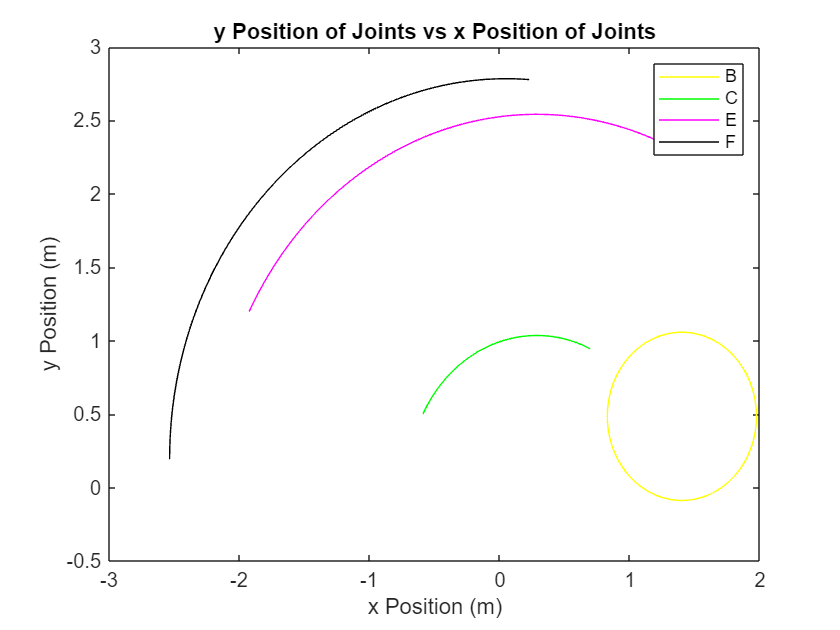


plot(new_B_x(:,1),new_B_y(:,1),"y-"); hold on

plot(new_C_x(:,1),new_C_y(:,1),"g-")

plot(new_E_x(:,1),new_E_y(:,1),"m-")

plot(new_F_x(:,1),new_F_y(:,1),"k-")

legend("B","C","E","F")
title("y Position of Joints vs x Position of Joints")
xlabel('x Position (m)')
ylabel('y Position (m)')
hold off

%This section reserved for table-making and data evaluation.
forcesmatrix(1,1:3)=vectorForceA_PA(1,1:3);
forcesmatrix(2,1:3)=vectorForceB_PA(1,1:3);
forcesmatrix(3,1:3)=vectorForceC_PA(1,1:3);
forcesmatrix(4,1:3)=vectorForceD_PA(1,1:3);
forcesmatrix(5,1:3)=vectorForceE_PA(1,1:3);
forcesmatrix(6,1:3)=vectorForceF_PA(1,1:3);
forcesmatrix(7,1:3)=vectorForceG_PA(1,1:3);
forcesmatrix(8,1:3)=vectorTorquein_PA(1,1:3);

forces_table=array2table(forcesmatrix, 'VariableNames',{'x','y','z'},'RowNames', {'FA(N)','FB(N)','FC(N)','FD(N)','FE(N)','FF(N)','FG(N)','Tin(N)',})

forces_table = 8×3 table
                       x                      y                      z         
              ___________________    ___________________    ___________________

    FA(N)      2277.7+4.6533e-06i     433.32-1.4798e-07i          0+0i         
    FB(N)     -2277.7-4.6533e-06i    -204.35+1.4798e-07i          0+0i         
    FC(N)     -2277.7-4.6533e-06i     349.22+1.4798e-07i          0+0i         
    FD(N)     -1408.5-4.6533e-06i     1512.6+1.4798e-07i          0+0i         
    FE(N)     -869.13+0i             -208.38+0i                   0+0i         
    FF(N)     -869.13+0i              252.69+0i                   0+0i         
    FG(N)     -869.13+0i              2119.8+0i                   0+0i         
    Tin(N)      

%These sections reserved for table-making and data evaluation.
Nmatrix(1,1:3)=NForceA_PA(1,1:3);
Nmatrix(2,1:3)=NForceB_PA(1,1:3);
Nmatrix(3,1:3)=NForceC_PA(1,1:3);
Nmatrix(4,1:3)=NForceD_PA(1,1:3);
Nmatrix(5,1:3)=NForceE_PA(1,1:3);
Nmatrix(6,1:3)=NForceF_PA(1,1:3);
Nmatrix(7,1:3)=NForceG_PA(1,1:3);
Nmatrix(8,1:3)=VectorNTorque_PA(1,1:3);

Nmatrix_table=array2table(Nmatrix, 'VariableNames',{'x','y','z'},'RowNames', {'FA(N)','FB(N)','FC(N)','FD(N)','FE(N)','FF(N)','FG(N)','Tin(N*m)',})

Nmatrix_table = 8×3 table
                         x                      y                     z         
                ___________________    ___________________    __________________

    FA(N)       -636.43+5.3102e-06i      418.1-1.6888e-07i         0+0i         
    FB(N)        617.92-5.3102e-06i    -223.76+1.6888e-07i         0+0i         
    FC(N)        539.17-5.3102e-06i      200.3+1.6888e-07i         0+0i         
    FD(N)        131.44-4.5378e-06i     1079.1-3.9764e-07i         0+0i         
    FE(N)        259.82+0i             -125.42+0i                  0+0i         
    FF(N)        148.75+0i              101.06+0i                  0+0i         
    FG(N)       -155.74+0i              923.35+0i                  0+0i         
    Tin(N*m)


matrix_omega(1,1:3)=vector_omegaAB_PA(1,1:3);
matrix_omega(2,1:3)=vector_omegaCB_PA(1,1:3);
matrix_omega(3,1:3)=vector_omegaED_PA(1,1:3);
matrix_omega(4,1:3)=vector_omegaFE_PA(1,1:3);
matrix_omega(5,1:3)=vector_omegaFG_PA(1,1:3);

omegamatrix_table=array2table(matrix_omega, 'VariableNames',{'x','y','z'},'RowNames', {'wAB(rad/s)','wCB(rad/s)','wED(rad/s)','wFE(rad/s)','wGF(rad/s)'})

omegamatrix_table = 5×3 table
                  x    y      z   
                  _    _    ______

    wAB(rad/s)    0    0    2.4241
    wCB(rad/s)    0    0    0.4895
    wED(rad/s)    0    0    1.2716
    wFE(rad/s)    0    0    1.0834
    wGF(rad/s)    0    0     1.347




matrix_alpha(1,1:3)=vector_alphaAB_PA(1,1:3);
matrix_alpha(2,1:3)=vector_alphaCB_PA(1,1:3);
matrix_alpha(3,1:3)=vector_alphaED_PA(1,1:3);
matrix_alpha(4,1:3)=vector_alphaFE_PA(1,1:3);
matrix_alpha(5,1:3)=vector_alphaGF_PA(1,1:3);


alpha_table=array2table(matrix_alpha, 'VariableNames',{'x','y','z'},'RowNames', {'alphaAB(rad/s^2)','alphaCB(rad/s^2)','alphaED(rad/s^2)','alphaFE(rad/s^2)','alphaGF(rad/s^2)'})

alpha_table = 5×3 table
                        x    y       z    
                        _    _    ________

    alphaAB(rad/s^2)    0    0           0
    alphaCB(rad/s^2)    0    0    -0.95773
    alphaED(rad/s^2)    0    0      1.2785
    alphaFE(rad/s^2)    0    0      1.4305
    alphaGF(rad/s^2)    0    0      1.5038




matrix_v(1,1:3)=vectorvB_A_PA(1,1:3);
matrix_v(2,1:3)=vectorvC_D_PA(1,1:3);
matrix_v(3,1:3)=vectorvE_D_PA(1,1:3);
matrix_v(4,1:3)=vectorvF_G_PA(1,1:3);
matrix_v=round(matrix_v,4);
vmatrix_table=array2table(matrix_v, 'VariableNames',{'x','y','z'},'RowNames', {'vBA(m/s)','vCD(m/s)','vED(m/s)','vFG(m/s)'})

vmatrix_table = 4×3 table
                   x          y       z
                _______    _______    _

    vBA(m/s)    -1.2241     0.6545    0
    vCD(m/s)    -1.2462    -0.0381    0
    vED(m/s)    -3.1599    -0.1144    0
    vFG(m/s)    -3.1924    -1.3874    0



matrix_a(1,1:3)=vectoraB_A_PA(1,1:3);
matrix_a(2,1:3)=vectoraC_D_PA(1,1:3);
matrix_a(3,1:3)=vectoraE_D_PA(1,1:3);
matrix_a(4,1:3)=vectoraF_G_PA(1,1:3);
matrix_a=round(matrix_a,4);
amatrix_table=array2table(matrix_a, 'VariableNames',{'x','y','z'},'RowNames', {'aBA(m/s^2)','aCD(m/s^2)','aED(m/s^2)','aFG(m/s^2)'})

amatrix_table = 4×3 table
                     x          y       z
                  _______    _______    _

    aBA(m/s^2)    -1.5865    -2.9674    0
    aCD(m/s^2)    -1.2044     -1.623    0
    aED(m/s^2)    -3.0314    -4.1333    0
    aFG(m/s^2)    -1.6951    -5.8492    0




matrix_as(1,1:3)=a_S1_A_PA(1,1:3);
matrix_as(2,1:3)=a_S2_A_PA(1,1:3);
matrix_as(3,1:3)=a_S3_D_PA(1,1:3);
matrix_as(4,1:3)=a_S4_G_PA(1,1:3);
matrix_as(5,1:3)=a_S5_G_PA(1,1:3);
matrix_as=round(matrix_as,4);
asmatrix_table=array2table(matrix_as, 'VariableNames',{'x','y','z'},'RowNames', {'aS1A(m/s^2)','aS2A(m/s^2)','aS3D(m/s^2)','aS4G(m/s^2)','aS5G(m/s^2)'})

asmatrix_table = 5×3 table
                      x          y       z
                   _______    _______    _

    aS1A(m/s^2)    -0.7933    -1.4837    0
    aS2A(m/s^2)    -1.3955    -2.2952    0
    aS3D(m/s^2)    -1.5194    -2.0716    0
    aS4G(m/s^2)    -2.3633    -4.9912    0
    aS5G(m/s^2)    -1.5998    -5.4896    0
